# Importing high-reslution sea surface temperature data with Matlab

The function getSST reads and store the sea surface temperature (SST)  produced on a daily basis by the JPL OurOcean group [1]. The dataset is described in more details in CHao et al. [2]. The SST data are available on a grid of 0.009 degrees, which represent  a horizontal resolution of approximatively  1 km. The second example works with the function borders.m and/or bordersm.m [3,4]

**References**

[1] [https://podaac.jpl.nasa.gov/dataset/JPL_OUROCEAN-L4UHfnd-GLOB-G1SST](https://podaac.jpl.nasa.gov/dataset/JPL_OUROCEAN-L4UHfnd-GLOB-G1SST)

[2] Chao, Y., Z. Li, J. D. Farrara, and P. Huang: Blended sea surface  temperatures from multiple satellites and in-situ observations for  coastal oceans, 2009: Journal of Atmospheric and Oceanic Technology, 26  (7), 1435-1446, 10.1175/2009JTECHO592.1

[3]    Greene, Chad A., et al. “The Climate Data Toolbox for MATLAB.”  Geochemistry, Geophysics, Geosystems, American Geophysical Union (AGU),  July 2019, doi:10.1029/2019gc008392.

[4] https://se.mathworks.com/matlabcentral/fileexchange/50390-borders

 Initialisation

clearvars;close all;clc;

## Get the SST data at single position for multiple days

% Select 13 days for the year 2015
targetDay =1:30:365;  % targetDay should be between 1 and  365
targetYear = 2015;

targetLat = 54; % target latitude
targetLon = 7;  % target longitude
SST = zeros(1,numel(targetDay));
time = NaT(1,numel(targetDay));

for ii=1:numel(targetDay),
    tic
        [SST(ii),time(ii)] = ...
            getSST(targetLat,targetLon,targetYear,targetDay(ii));
        toc
end

Elapsed time is 13.321814 seconds.
Elapsed time is 13.938948 seconds.
Elapsed time is 13.459872 seconds.
Elapsed time is 13.534891 seconds.
Elapsed time is 13.351532 seconds.
Elapsed time is 13.235077 seconds.
Elapsed time is 13.683475 seconds.
Elapsed time is 13.570332 seconds.
Elapsed time is 13.253393 seconds.
Elapsed time is 13.234480 seconds.
Elapsed time is 13.270598 seconds.
Elapsed time is 13.461531 seconds.
Elapsed time is 13.371351 seconds.


### Display the time series

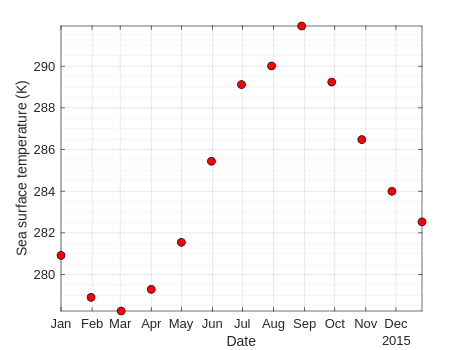

clf;close all;
figure
plot(time,SST,'ko','markerfacecolor','r')
grid on
grid minor
axis tight
xlabel('Date');
ylabel('Sea surface temperature (K)')

set(gcf,'color','w');

## Get the SST data at multiple position for a single day

clearvars;close all;clc;
targetDay =[1 180]; % first and 180th day of the year
targetYear = 2015;
minLat = 53;
maxLat = 64;
minLon = 4;
maxLon = 14;
targetLat = [minLat,maxLat];  % from minLat to maxLat
targetLon = [minLon,maxLon];   % from minLon to maxLon
clear SST 
resolution = 0.03; % deg
[lon,lat] = meshgrid(targetLon(1):resolution:targetLon(end),...
    targetLat(1):resolution:targetLat(end));
[Nlat,Nlon]=size(lat);
SST = NaN(numel(targetYear)*numel(targetDay),Nlat,Nlon);

for ii=1:numel(targetDay)
    tic
    [SST(ii,:,:),time(ii),~,~,mask] = ...
        getSST(targetLat,targetLon,targetYear,targetDay(ii),...
        'resolution',resolution);
    toc
end

Elapsed time is 30.040912 seconds.
Elapsed time is 30.042388 seconds.


### Display the SST map

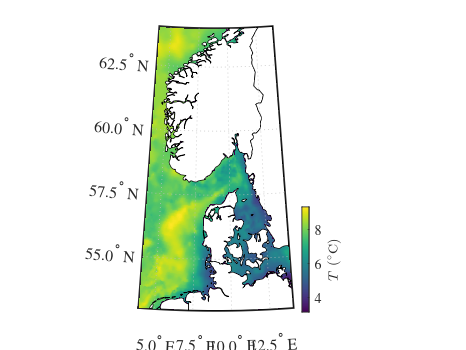

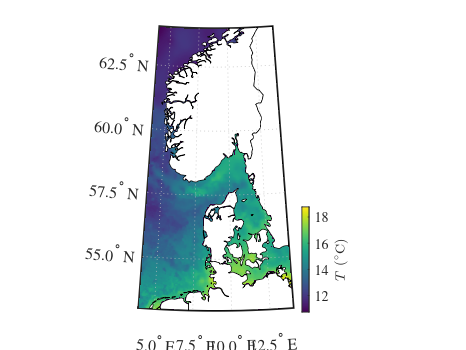

SST(mask==0) = nan; % Apply the mask to remove SST data related to land area
if ~exist('borders.m','file')
    error('The example file uses the functions borders.m and/or bordersm.m by Chad Green. They can be downlaoded here: https://mathworks.com/matlabcentral/fileexchange/50390-borders');
end

if numel(size(SST))>2, Ndays = size(SST,1); else Ndays = 1; end

clf;close all;
for ii=1:Ndays,
    figure
    if  license('test','MAP_Toolbox')
        worldmap(targetLat,targetLon)
        geoshow(lat,lon,squeeze(SST(ii,:,:))-273.15, 'DisplayType','texturemap')
        hold on
        bordersm('Norway','facecolor','white')
        bordersm('Sweden','facecolor','white')
        bordersm('Denmark','facecolor','white')
        bordersm('Germany','facecolor','white')
        bordersm('Netherlands','facecolor','white')
        colorbar
    else
        figure
        imagesc(lon(1,:),lat(:,1),squeeze(SST(ii,:,:))-273.15);axis xy
        borders('Norway','facecolor','white')
        borders('Sweden','facecolor','white')
        borders('Denmark','facecolor','white')
        borders('Germany','facecolor','white')
        borders('Netherlands','facecolor','white')
        axis equal
        ylim([targetLat])
        xlim([targetLon])
        ylabel('latitude');
        xlabel('Longitude');
    end
    
    if exist('viridis.m','file')
        colormap('viridis');
    else
        colormap('hot');
    end
    caxis([min(reshape(SST(ii,:,:),1,[])-273.15) max(reshape(SST(ii,:,:),1,[])-273.15)])
    set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')
        cb2 = colorbar('location','eastoutside');
        x1=get(gca,'position');x=get(cb2,'Position');x(3)=0.015; x(4)=0.3;set(cb2,'Position',x);set(gca,'position',x1)
        cb2.Label.String = '$T$ ($^{\circ}$C)';
        cb2.Label.Interpreter = 'latex';
        cb2.AxisLocation = 'out';
    set(gcf,'color','w')
end